type StateFcn.m

function x = StateFcn(x)
    dt = 0.05;
    x = x + StateFcnContinuous(x)*dt;
end

function dxdt = StateFcnContinuous(x)
    dxdt = [x(2); (1-x(1)^2)*x(2)-x(1)];
end
    
    


type MeasurementNoiseNonAdditiveFcn.m

function yk = MeasurementNoiseNonAdditiveFcn(xk,vk)
    yk = xk(1)*(1+vk);
end


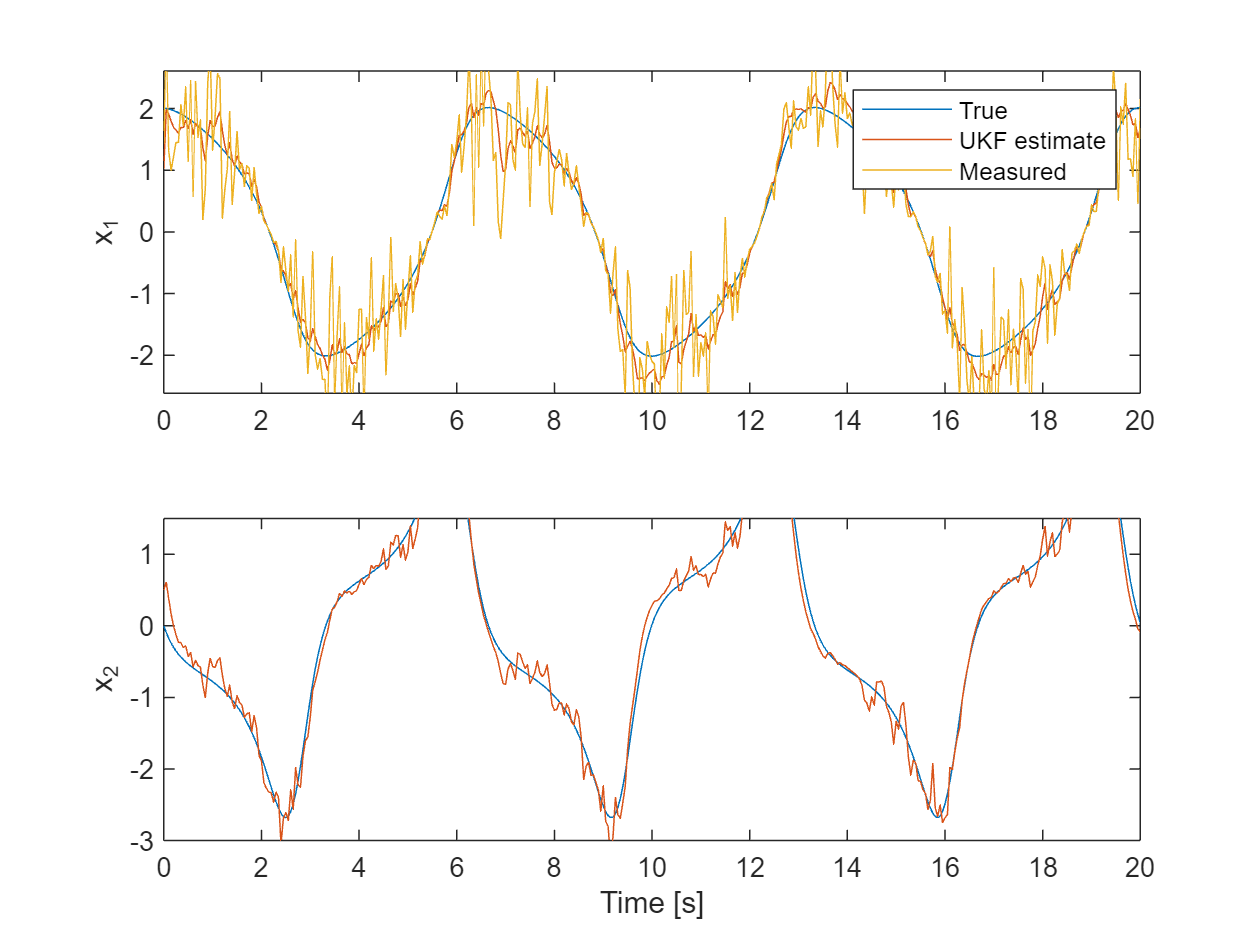


initialGuess= [-1;0.5];

ukf = unscentedKalmanFilter(...
    @StateFcn,...
    @MeasurementNoiseNonAdditiveFcn,...
    initialGuess,...
    'HasAdditiveMeasurementNoise',false);
    
R = 0.2; % Variance of the measurement noise v[k]
ukf.MeasurementNoise = R;

ukf.ProcessNoise = diag([0.02 0.1]);
    
T = 0.05; % [s] Filter sample time
timeVector = 0:T:20;
[~,xTrue]=ode45(@vdp1,timeVector,[2;0]);

rng(1);
yTrue = xTrue(:,1);
yMeas = yTrue .* (1+sqrt(R)*randn(size(yTrue)));

Nsteps = numel(yMeas); % Number of time steps
xCorrectedUKF = zeros(Nsteps,2); % Corrected state estimates
PCorrected = zeros(Nsteps,2,2); % Corrected state estimation error covariances
e = zeros(Nsteps,1); % Residuals (or innovations)

for k=1:Nsteps
    
    e(k) = yMeas(k) - vdpMeasurementFcn(ukf.State); % ukf.State is x[k|k-1] at this point
 
    [xCorrectedUKF(k,:), PCorrected(k,:,:)] = correct(ukf,yMeas(k));

    predict(ukf);
end

figure();
subplot(2,1,1);
plot(timeVector,xTrue(:,1),timeVector,xCorrectedUKF(:,1),timeVector,yMeas(:));
legend('True','UKF estimate','Measured')
ylim([-2.6 2.6]);
ylabel('x_1');
subplot(2,1,2);
plot(timeVector,xTrue(:,2),timeVector,xCorrectedUKF(:,2));
ylim([-3 1.5]);
xlabel('Time [s]');
ylabel('x_2');

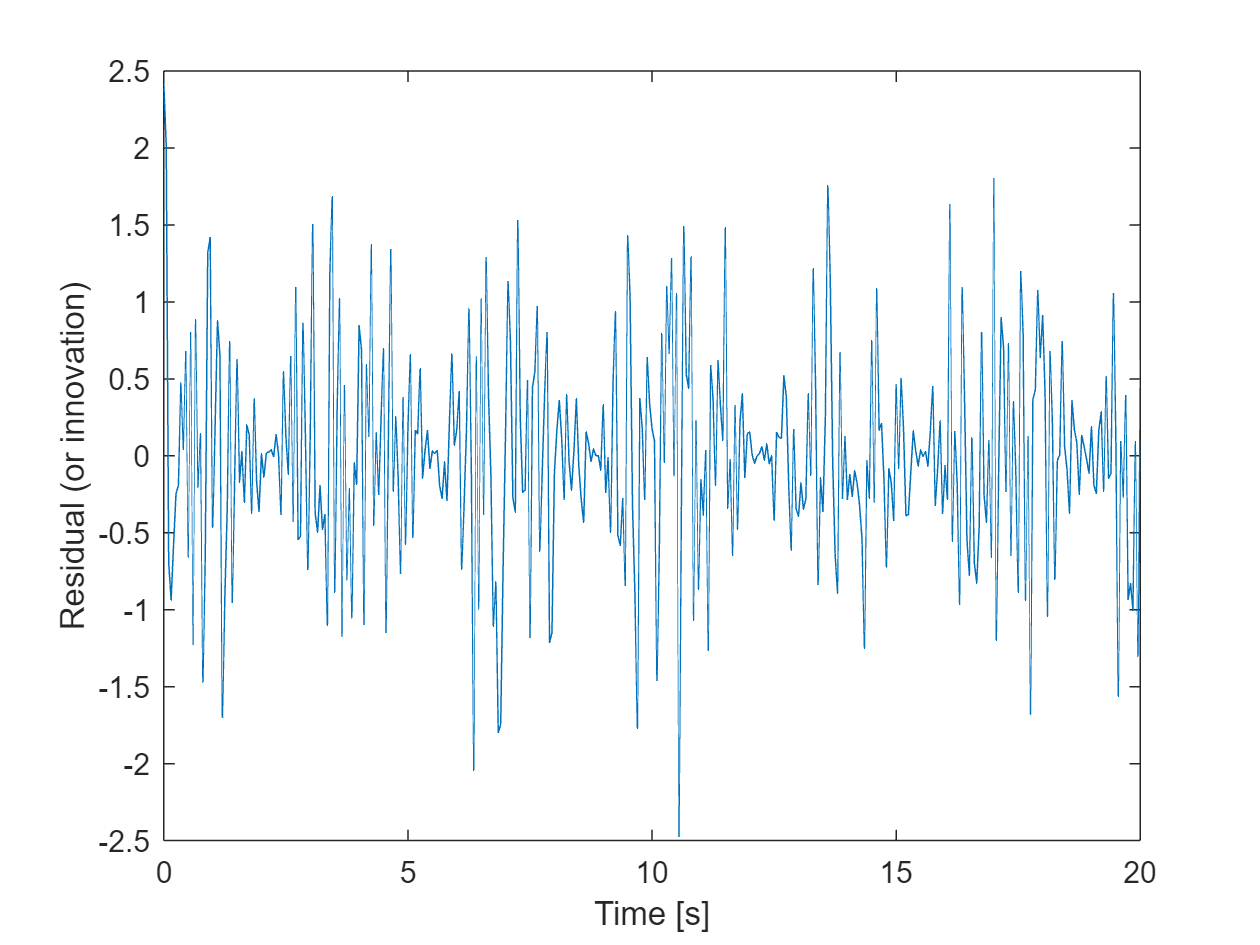

figure();
plot(timeVector, e);
xlabel('Time [s]');
ylabel('Residual');

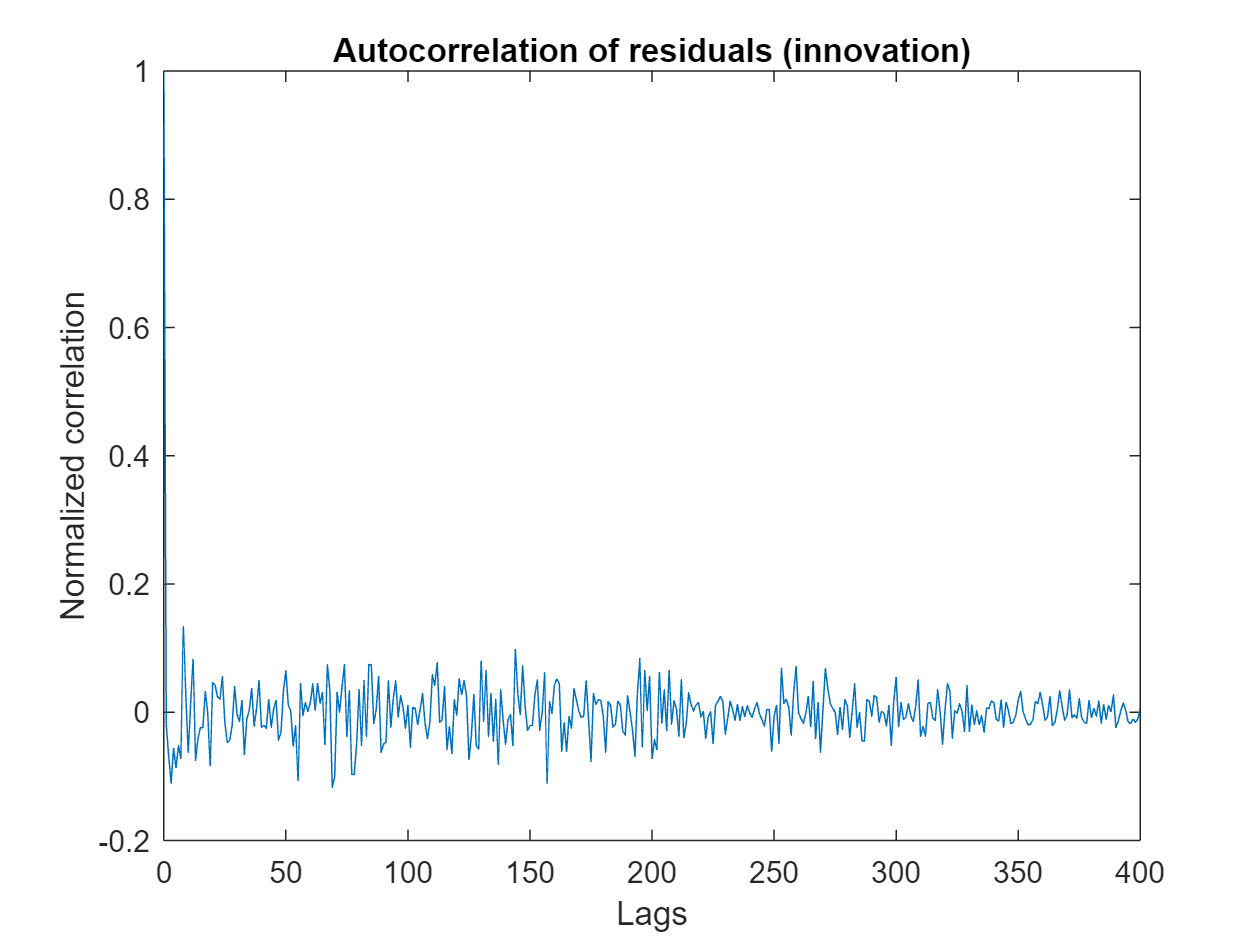

[xe,xeLags] = xcorr(e,'coeff'); % 'coeff': normalize by the value at zero lag
% Only plot non-negative lags
idx = xeLags>=0;
figure();
plot(xeLags(idx),xe(idx));
xlabel('Lags');
ylabel('Normalized correlation');
title('Autocorrelation of residuals (innovation)');

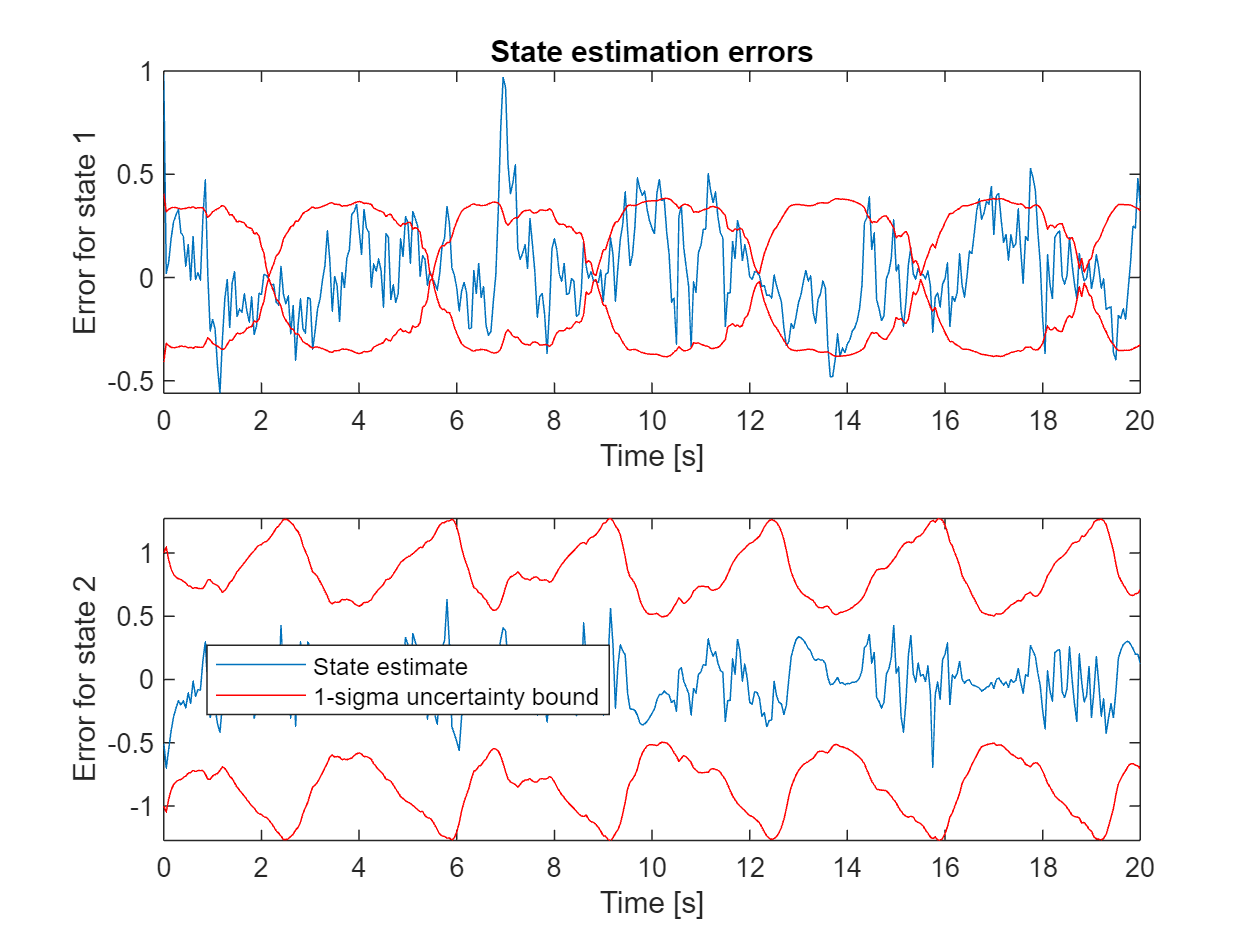


eStates = xTrue-xCorrectedUKF;
figure();
subplot(2,1,1);
plot(timeVector,eStates(:,1),...               % Error for the first state
    timeVector, sqrt(PCorrected(:,1,1)),'r', ... % 1-sigma upper-bound
    timeVector, -sqrt(PCorrected(:,1,1)),'r');   % 1-sigma lower-bound
xlabel('Time [s]');
ylabel('Error for state 1');
title('State estimation errors');
subplot(2,1,2);
plot(timeVector,eStates(:,2),...               % Error for the second state
    timeVector,sqrt(PCorrected(:,2,2)),'r', ...  % 1-sigma upper-bound
    timeVector,-sqrt(PCorrected(:,2,2)),'r');    % 1-sigma lower-bound
xlabel('Time [s]');
ylabel('Error for state 2');
legend('State estimate','1-sigma uncertainty bound',...
    'Location','Best');

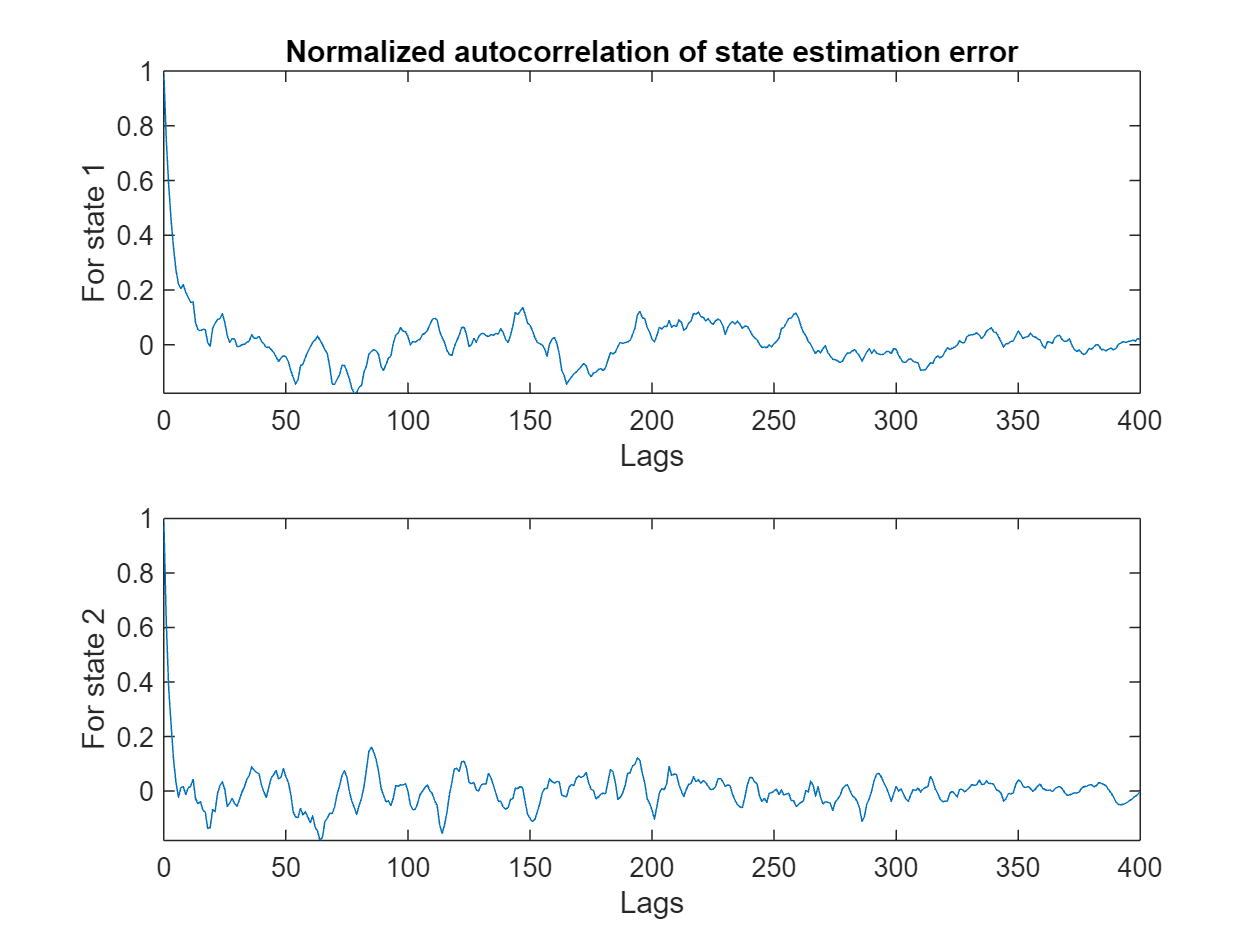


[xeStates1,xeStatesLags1] = xcorr(eStates(:,1),'coeff'); % 'coeff': normalize by the value at zero lag
[xeStates2,xeStatesLags2] = xcorr(eStates(:,2),'coeff'); % 'coeff'
% Only plot non-negative lags
idx = xeStatesLags1>=0;
figure();
subplot(2,1,1);
plot(xeStatesLags1(idx),xeStates1(idx));
xlabel('Lags');
ylabel('For state 1');
title('Normalized autocorrelation of state estimation error');
subplot(2,1,2);
plot(xeStatesLags2(idx),xeStates2(idx));
xlabel('Lags');
ylabel('For state 2');